Joseph Ntaimo Feb 2024

# 2.12 Lab 4 Motor Modeling

### Motor Parameters

We are using a Modern Robotics 12DC Motor with a 60RPM Planetary gearset.

Look at the motor page(s) to fill in the following

- Motor stall torque constant $K_{t-\textrm{stall}}$

- Back EMF Constant $\textrm{Ke}$

- Estimated nominal torque 

- Gear ratio $r$

- Armature resistance $R$

#### Electrical Constants

Motor torque constant

t_stall = 1.47; %kgcm 
stall_current = 9.2; %(A) Stall current of the motor 
Kt_stall = (t_stall*9.81/100)/stall_current %(Nm/A) motor torque constant' 

Kt_stall = 0.0157

Back EMF Constant

V = 12; %(v) Voltage of the motor 
RPM = 5800; %(Rev/min) 
Ke = V/(RPM/60*2*pi) %(V/(rad/s)) 

Ke = 0.0198

What will you use for the actual Kt estimate? Hint, you may have to tweak this later

Kt = (Kt_stall+Ke)/2 %(Nm/a) or (V/(rad/s))

Kt = 0.0177

Gear ratio

r = 99.5; %gear ratio 

Armature resistance

R = 1.3; %(Ohms) Armature resistance

#### Mechanical Constants

Look at the motor page(s) and use the pre-filled parameters to fill in the following

- Rotor volume $v_{\textrm{rotor}}$

- Rotor mass $m_{\textrm{rotor}}$

- Rotor inertia $I_{\textrm{rotor}}$

Motor Rotor inertia

r_rotor = 1/8*25.4/1000/2; %(m)radius of the rotor
l_rotor = 0.075; %(m) approx length of rotor
rho_rotor = 7.75;%(kg/m^3) density of steel rotor
v_rotor = pi*r_rotor^2*l_rotor%(m^3) volume of rotor

v_rotor = 5.9380e-07

m_rotor = v_rotor*rho_rotor; %(kg) mass of rotor
I_rotor = m_rotor*r_rotor^2 %(kgm^2)

I_rotor = 1.1598e-11

Motor and link parameters 

m_motor = 0.486; %(kg) mass of the motor
r_motor = 0.036/2;%(m) radius of the motor
m_arm = 0.059; %(kg) mass of a single arm
Lhole = 0.024; %(m) distance between large holes on the arm
L1 = Lhole*7; %(m) length of first linkage
L2 = Lhole*9; %(m) length of second linkage
L = 0.216; %(m) length of full C channel

Hint - you will need the [parallel axis theorem](https://en.wikipedia.org/wiki/Parallel_axis_theorem) and some useful [moments of inertia](https://en.wikipedia.org/wiki/List_of_moments_of_inertia)

Il_2 = 1/3*m_arm*L2^2 %(kgm^2) Load moment of inertia for second motor

Il_2 = 9.1757e-04

Im = 1/2*m_motor*r_motor^2; %(kgm^2) Motor moment of inertia
Il_1 = Im + (Im + m_motor*L1^2)+ 1/3*m_arm*L1^2 + (1/3*m_arm*L2^2 +m_arm*L1^2)%(kgm^2) Load moment of inertia for first motor

Il_1 = 0.0170

Answer the following

- What is the ratio between the two motor inertias? $\frac{I_{\textrm{L1}} }{I_{\textrm{L2}} }$

- Why is this ratio so large?

- What does this ratio say about the amount of gain your motors will need to move quickly? Which motor should have notably higher gains?

# Checkoff 1

Inertia_ratio = Il_1/Il_2

Inertia_ratio = 18.5405

Viscous damping

b = 0.00; %(Nm/(rad/s)) Viscous damping

#### Derived parameters

Motor constant

Km = Kt/sqrt(R) %(Nm/w^1/2)

Km = 0.0155

Effective inertia

I1 = Il_1 + r^2*I_rotor %(kgm^2)

I1 = 0.0170

I2 = Il_2 + r^2*I_rotor

I2 = 9.1768e-04

Effective damping

B = b + r^2*Km^2 %(Nm/(rad/s))

B = 2.3902

Input gain

k = r*Kt/R %(Nm/v)

k = 1.3559

Let's make the transfer function!

m1 = generateMotorModel(I1, k, B);
m2 = generateMotorModel(I2, k, B);

Let's take a look at the poles and zeros on the root locus. This can give us insight into how to control this system.

- Is Kp control stable?

- What happens to the closed loop natural frequency of the system as kp increases?

- What happens to damping as kp increases?

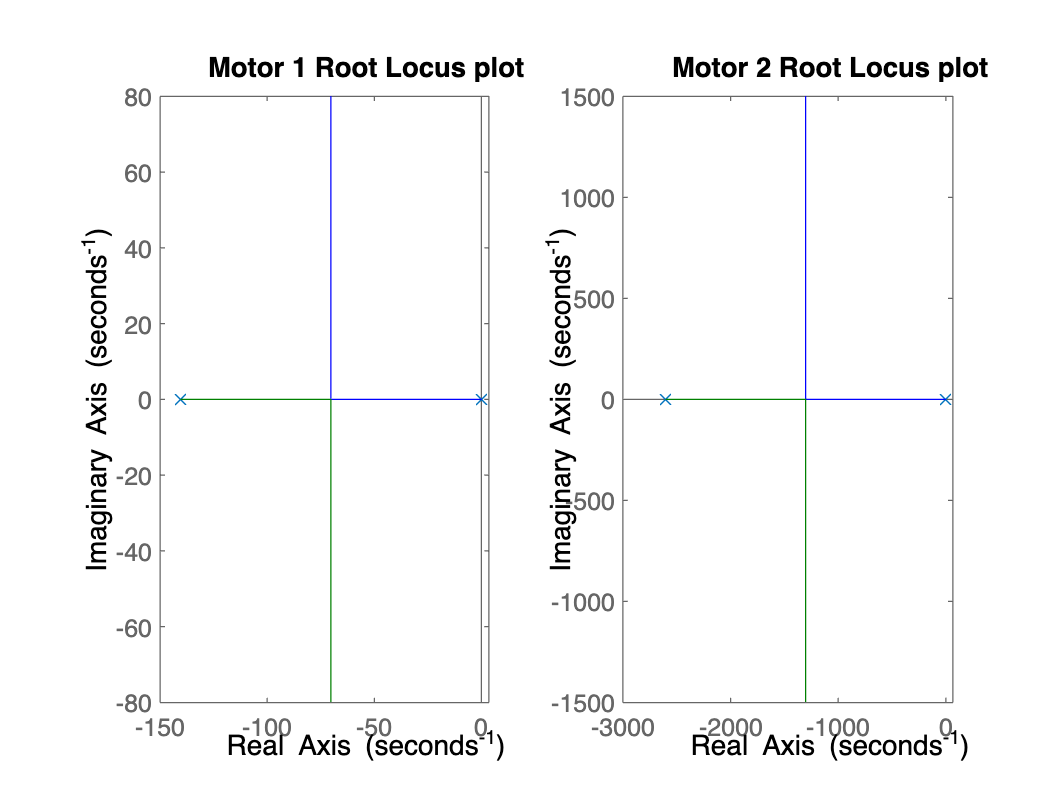

figure;
subplot(1,2,1);
rlocus(m1)
title("Motor 1 Root Locus plot");
subplot(1,2,2);
rlocus(m2);
title("Motor 2 Root Locus plot")

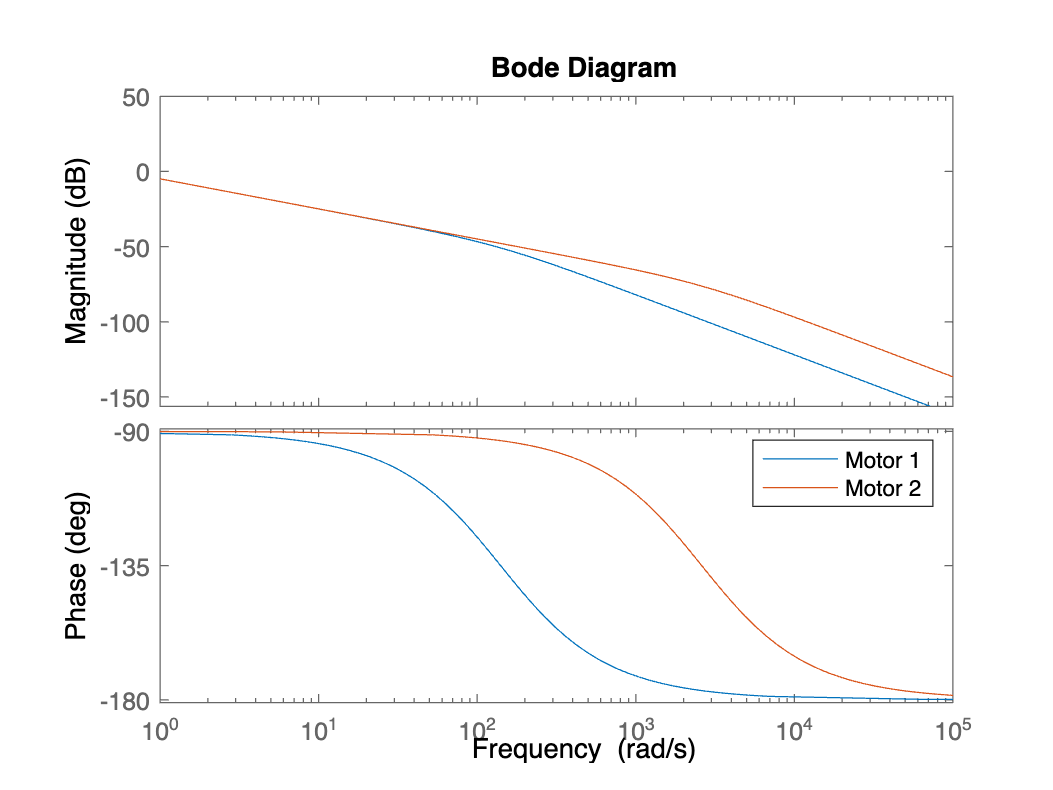

figure;
bode(m1)
hold on
bode(m2);
legend("Motor 1", "Motor 2")
hold off

### Time Responses

Let's see how fast these motors respond to an open loop step in voltage and assess if it makes sense

Since the motors will continuously rotate due to a step in voltage, reading position doesn't make much sense because it will keep increasing. 

- Instead of having position as the output of the step, what is a simple way to make the output velocity? Implement it.

- How can you make a step of 12V for the motor?

- Try switching the gear ratio to the gear ratio for the faster 312 RPM motors we have for the mobile robot drivetrain. Are these motors actually faster?

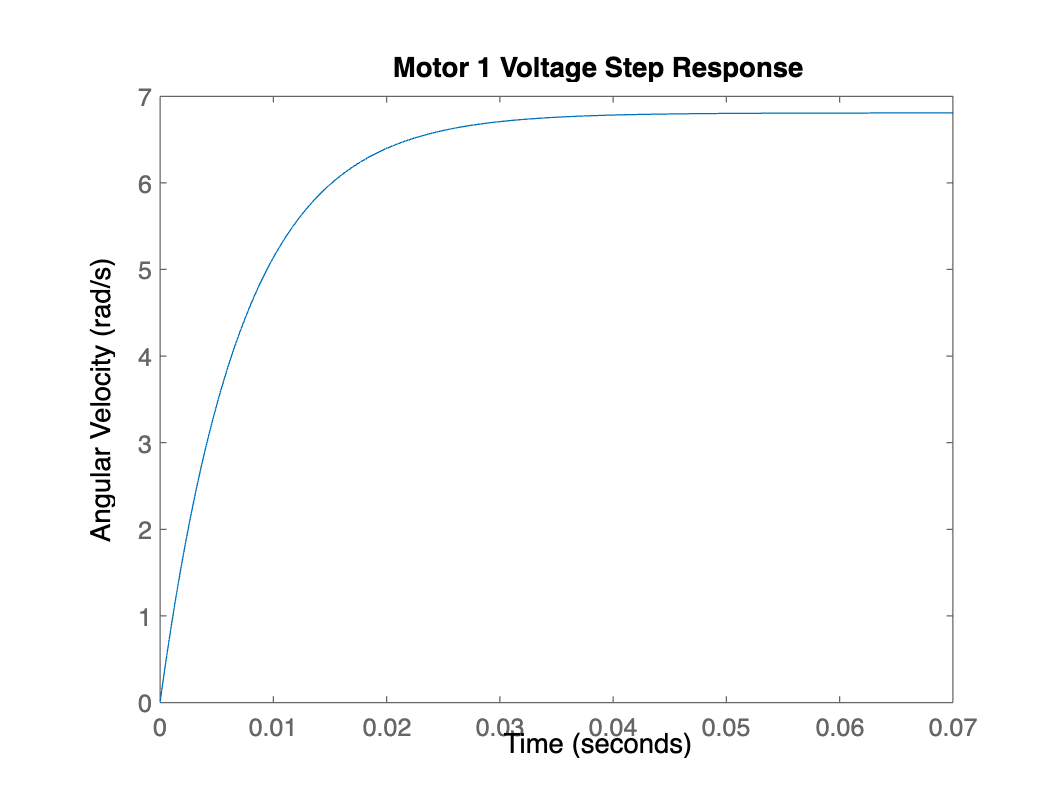

s = tf('s');
step(s*m1*V);
title("Motor 1 Voltage Step Response")
ylabel("Angular Velocity (rad/s)")

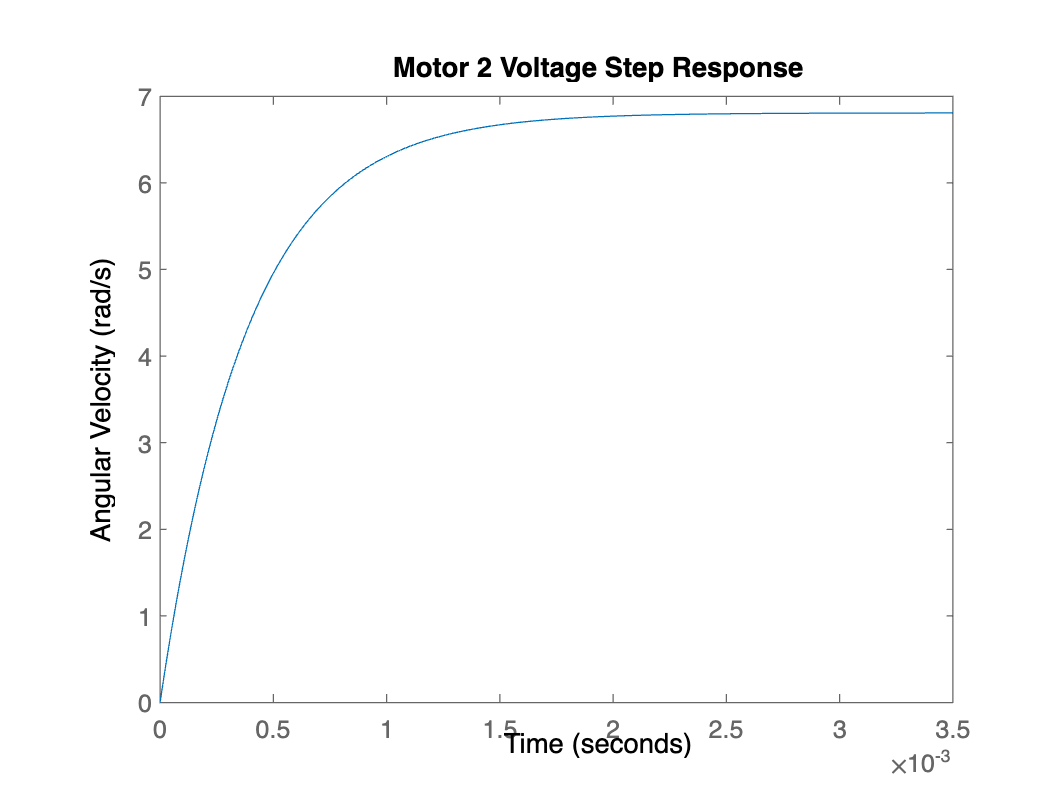

step(s*m2*V);
title("Motor 2 Voltage Step Response")
ylabel("Angular Velocity (rad/s)")

- Does the steady state velocity make sense for the motor given it's RPM rating? 

- How could you adjust your model to make the steady state velocity make sense? (Hint - Kt)

- What is the time constant estimate for both of the motors

Helpful equation $V_{\textrm{RPM}} =\frac{V_{\frac{\textrm{rad}}{s}} \cdot 60}{2\cdot \pi }$

ss_vel = 0;
tau1 = 0;
tau2 = 0;

Let's overlay the plots to compare the speeds of the motors

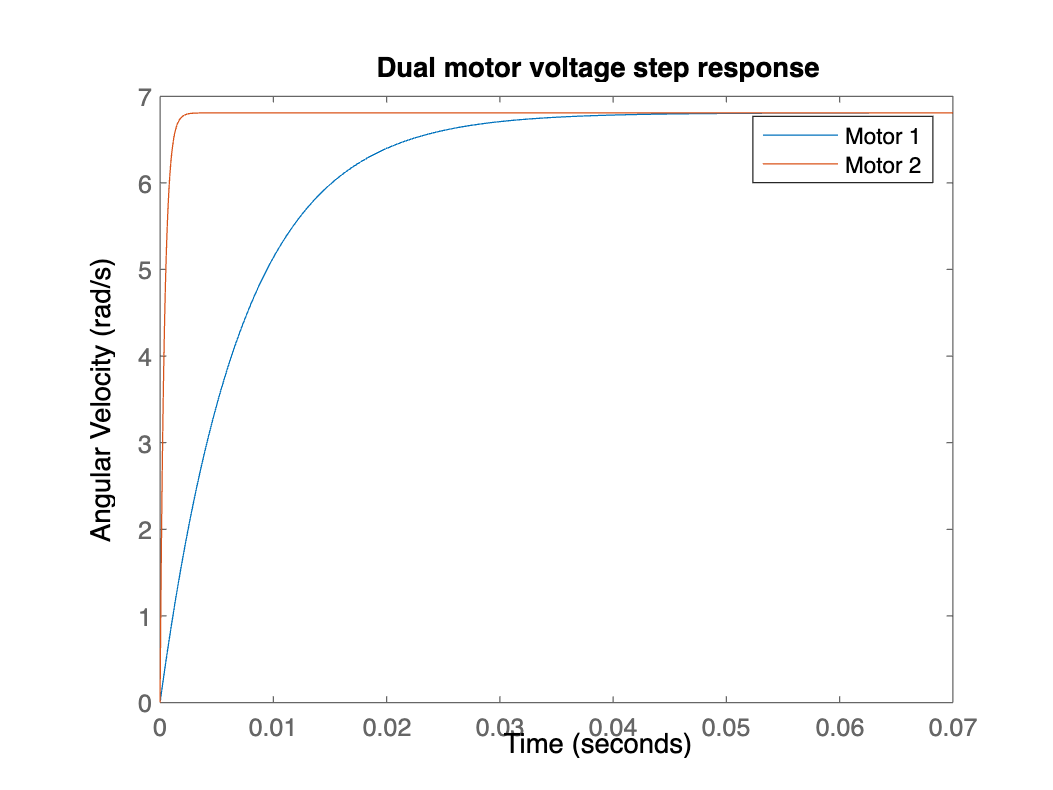

figure;
hold on;
step(s*m1*V);
step(s*m2*V);
title("Dual motor voltage step response");
legend("Motor 1", "Motor 2");
ylabel("Angular Velocity (rad/s)");
hold off;

- Which motor is faster?

- Does that make sense? Why?

# Checkoff 2

## Controller design time!

wc = 100;

Evaluate the plant's phase margin at crossover

plant_phase = rad2deg(angle(evalfr(m1,wc*1i)))

plant_phase = -125.4417

plant_gain = norm(evalfr(m1, wc*1i))

plant_gain = 0.0046

plant_phase_margin = plant_phase - (-180);

See how much more phase margin the plant needs to meet phase margin

desired_pm = 50;
controller_phase = desired_pm-plant_phase_margin

controller_phase = -4.5583

The lead will contribute phase and the lag will remove phase, but we want the combination to be near the controller phase

%center a lead controller at crossover
% alpha = 10; %gives 55 deg of phase
% lead_phase = rad2deg(asin((alpha-1)/(alpha+1))) %degrees
lead_phase = 55 %deg

lead_phase = 55

alpha = (-1-sind(lead_phase))/(sind(lead_phase)-1) %pick an alpha that gives us desired phase

alpha = 10.0590

Td = 1/(wc*sqrt(alpha)); %center lead at crossover
lead = tf([alpha*Td 1],[Td, 1]);
lag_phase_loss = 20; %degrees
Ti = tand(90-lag_phase_loss)/wc

Ti = 0.0275

lag = tf([Ti, 1],[Ti, 0]);
Kp = 1/(plant_gain*sqrt(alpha)*norm(evalfr(lag, wc*1i)))

Kp = 64.1053


pid1 = Kp*lead*lag;

Plot the controller to make sure it makes sense

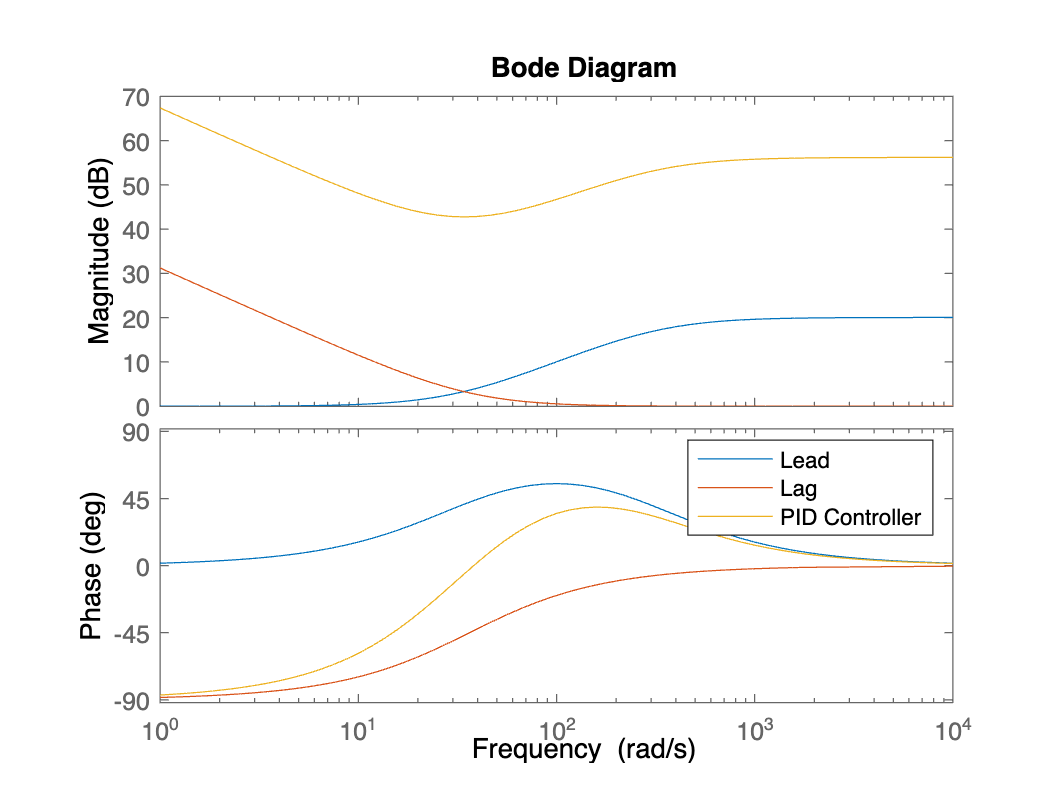

figure;
bode(lead);
hold on;
bode(lag);
bode(pid1);
legend("Lead", "Lag", "PID Controller");
hold off;

Plot the controller and the compensated plant to make sure it makes sense

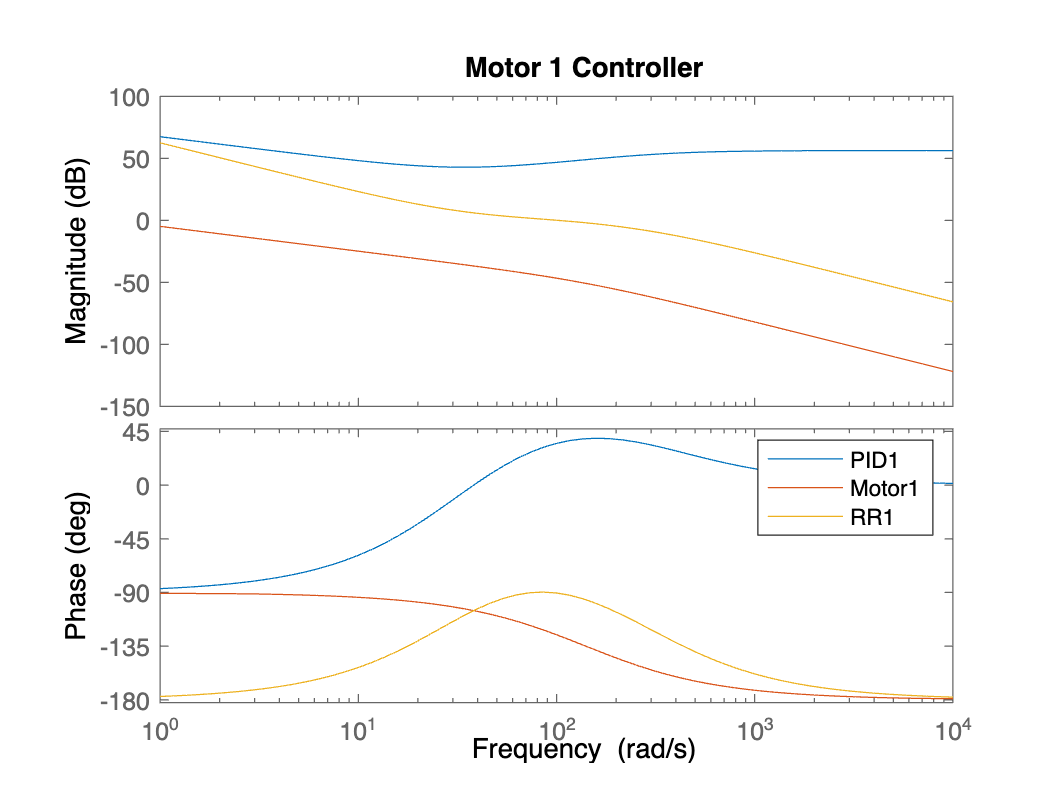

RR1 = pid1*m1;
figure;
hold on;
bode(pid1);
bode(m1);
bode(RR1);
title("Motor 1 Controller");
legend("PID1", "Motor1", "RR1");
hold off;

Check the phase margin at crossover

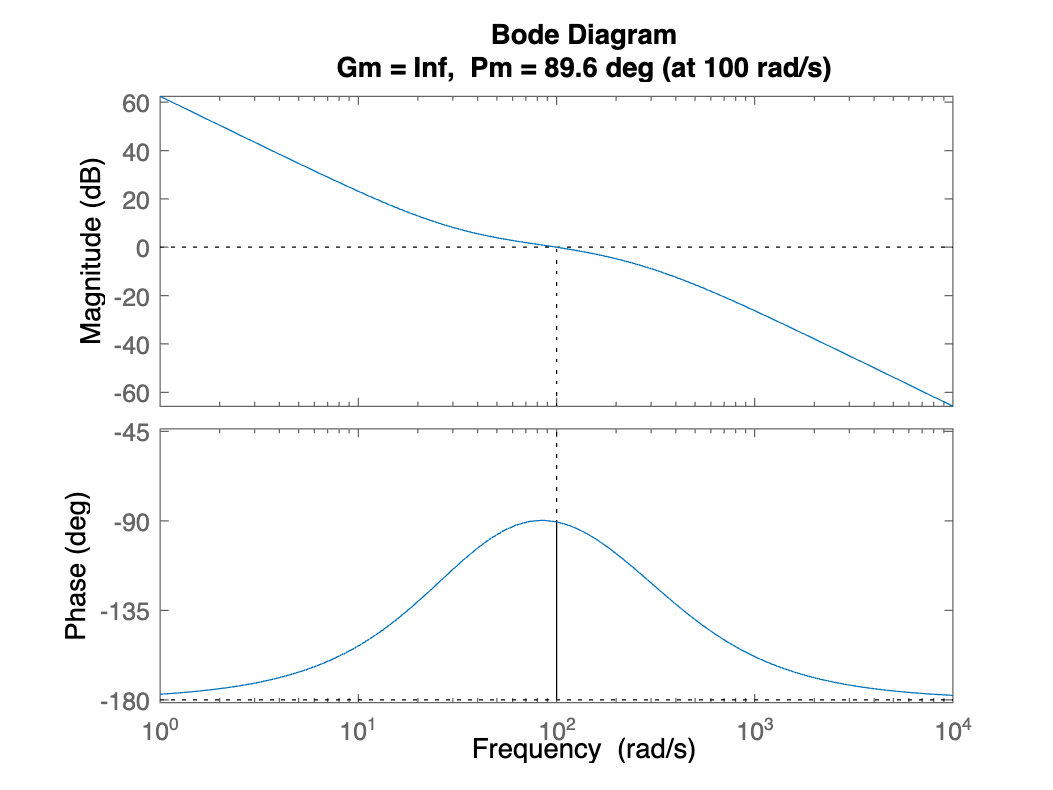

margin(RR1)

### Time domain

Let's check the step responses to make sure they are acceptable

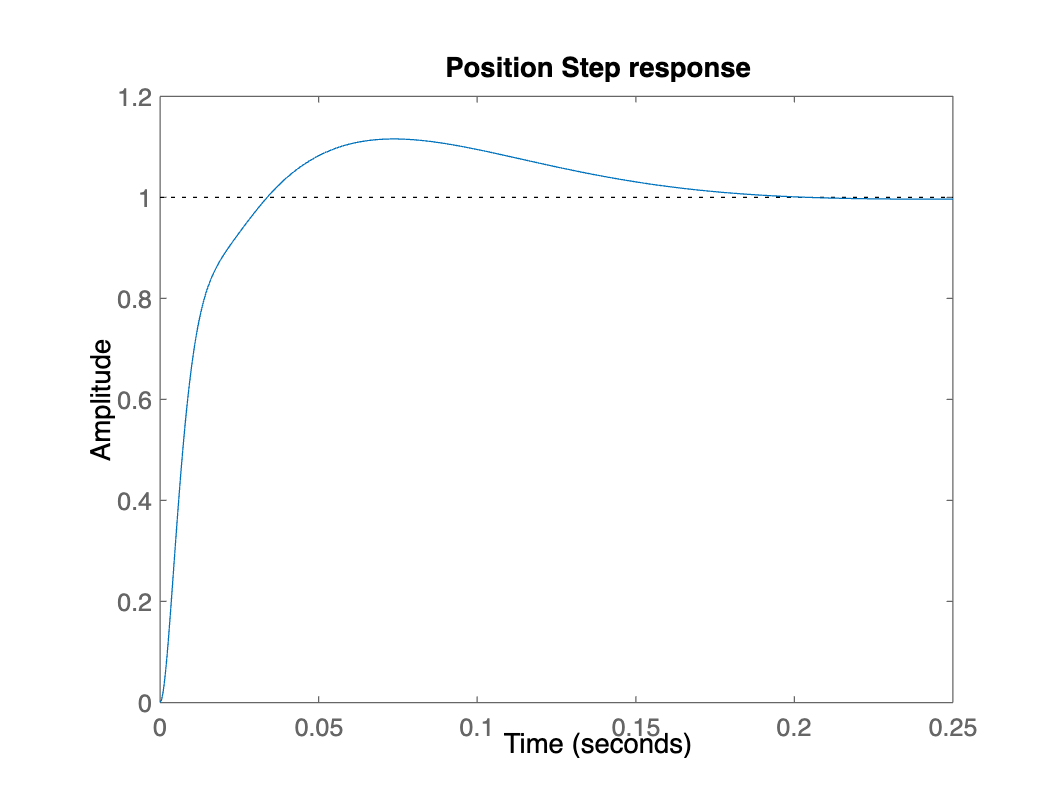

CL1 = feedback(RR1,1);
ControlEffort = feedback(pid1,m1);
step(CL1);
title("Position Step response");

step(ControlEffort)
title("Voltage Step Response")

Notice the voltage requirement is comically high. What if we used a smoother step?

First we generate the "step"

sigmoidDuration = 0.1; %seconds
finalTime = 2; %seconds
finalValue = 1; %radian
stepSize = 0.001; %seconds
[t, stepInput] = generateSigmoidStepInput(sigmoidDuration, stepSize, finalTime, finalValue);

Then we simulate the response to it

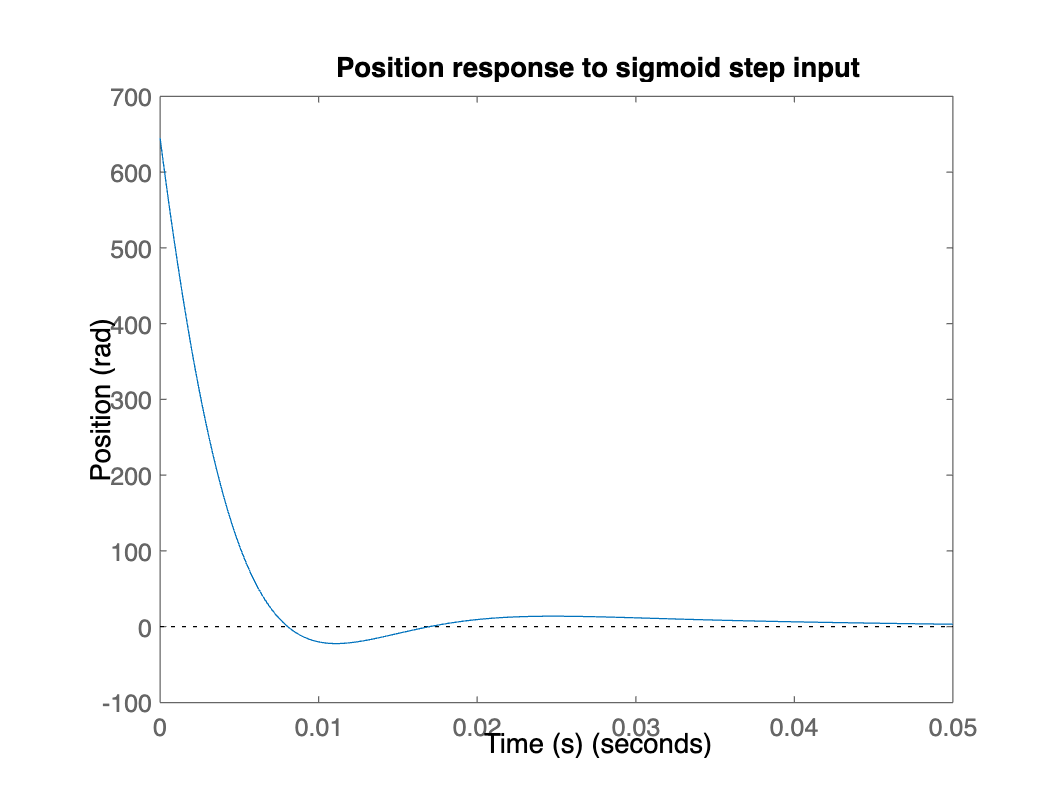

sigStepPos = lsim(CL1, stepInput, t);
title("Position response to sigmoid step input");
xlabel("Time (s)");
ylabel("Position (rad)");

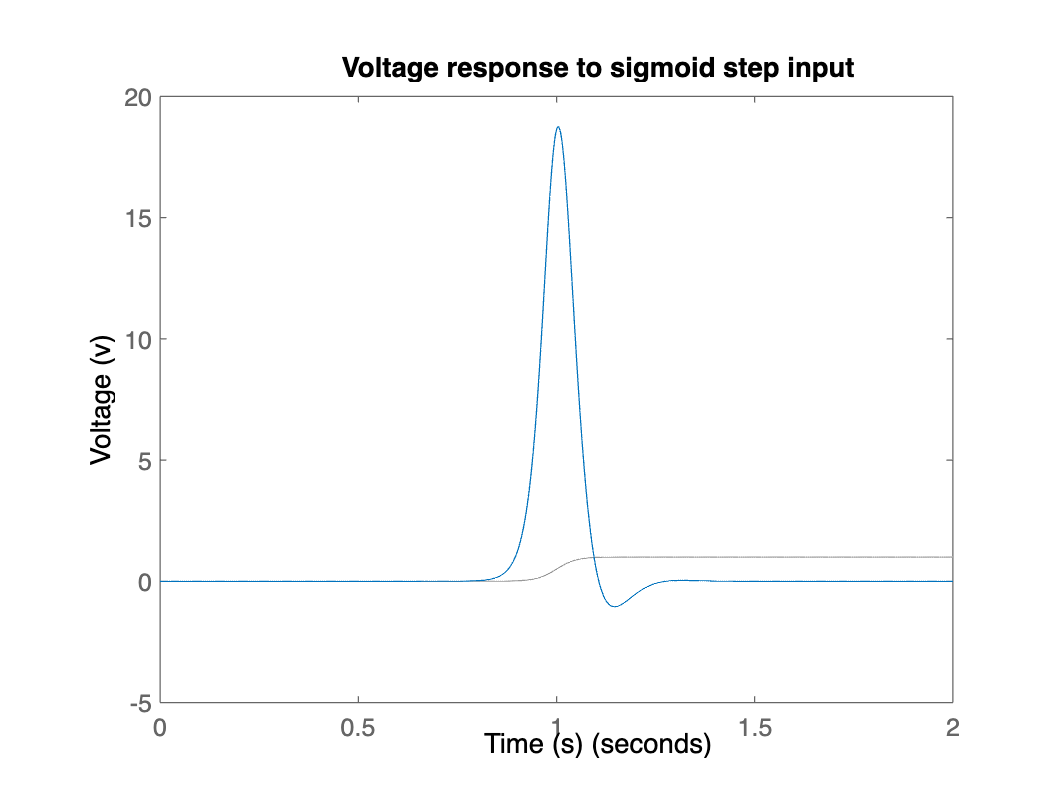

lsim(ControlEffort, stepInput, t);
title("Voltage response to sigmoid step input");
xlabel("Time (s)");
ylabel("Voltage (v)")

What if the step was a cartsian step?

[theta1, ~] = inverseKinematics(stepInput, 30)

theta1 =     0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895    0.7895


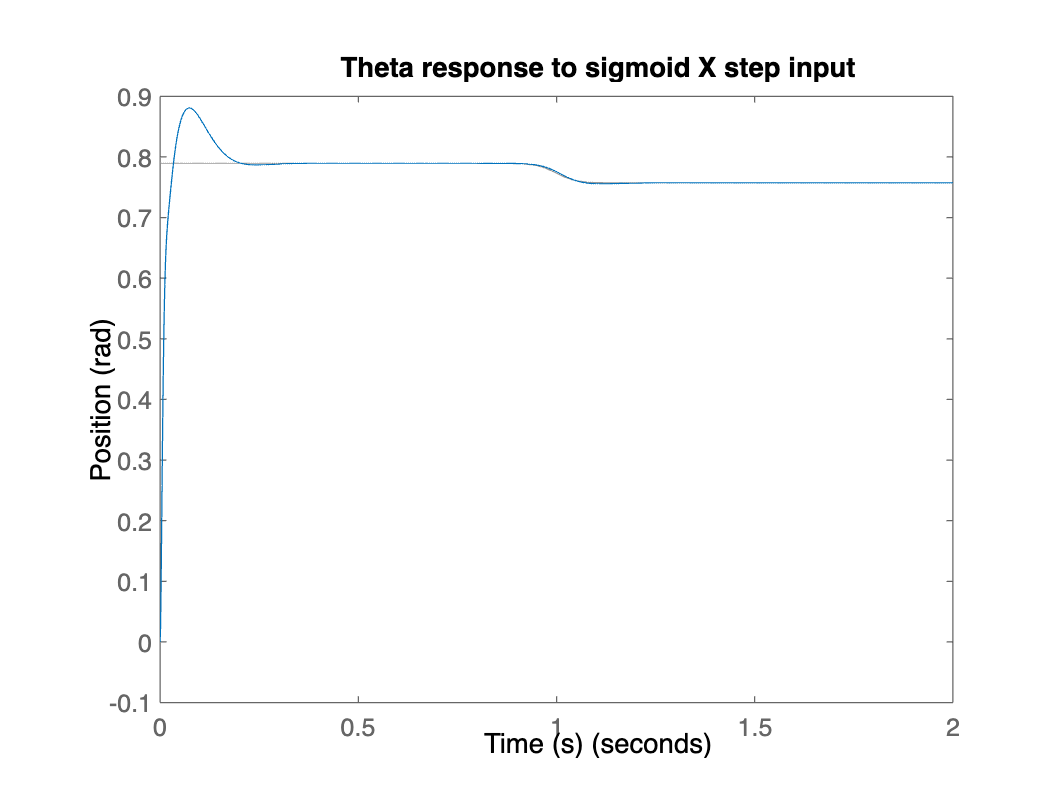

lsim(CL1, theta1, t);
title("Theta response to sigmoid X step input");
xlabel("Time (s)");
ylabel("Position (rad)");

Let's also consider the response to a sinusoidal input

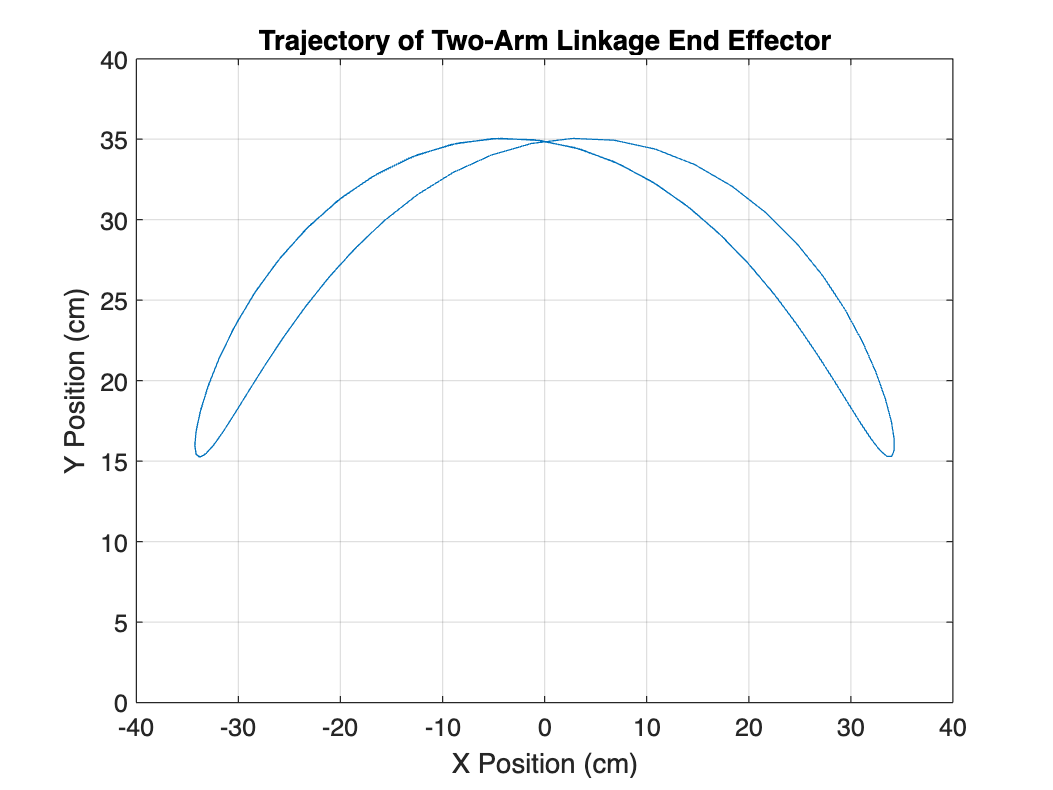

% Example theta1 and theta2 as time-varying vectors
t = 0:0.1:10; % Time vector
theta1 = pi/2 + sin(t);
theta2 = cos(t);

% Compute corresponding x and y using forward kinematics
[x, y] = forwardKinematics(theta1, theta2);

% Plotting
figure;
plot(x, y);
xlim([-40, 40]);
ylim([0,40]);
xlabel('X Position (cm)');
ylabel('Y Position (cm)');
title('Trajectory of Two-Arm Linkage End Effector');
grid on;

function model = generateMotorModel(I, k, B)
    a1 = I/k;
    a2 = B/k;
    model = tf(1, [a1, a2, 0]);
end

function [t, stepInput] = generateSigmoidStepInput(transitionDuration, dt, endTime, finalValue)
    % Generate time vector
    t = 0:dt:endTime;
    
    % Calculate transition start and end times
    % Assuming transition is centered in the time interval
    transitionStart = (endTime - transitionDuration) / 2;
    transitionEnd = (endTime + transitionDuration) / 2;
    
    % Steepness of the transition
    % Adjust k for a sharper or smoother transition
    k = 4 / transitionDuration; 
    
    % Generate sigmoid step input
    stepInput = finalValue ./ (1 + exp(-k * (t - (transitionStart + transitionEnd) / 2)));
end

function [x, y] = forwardKinematics(theta1, theta2)
    L_HOLE = 2.4; % distance between large holes in cm
    L1 = L_HOLE * 7; % Length of the first arm in cm
    L2 = L_HOLE * 9; % Length of the second arm in cm
    
    % Calculate the position in task space
    x = L1*cos(theta1) + L2*cos(theta1 + theta2);
    y = L1*sin(theta1) + L2*sin(theta1 + theta2);
end

function [theta1, theta2] = inverseKinematics(x, y)
    L_HOLE = 2.4; % distance between large holes in cm
    L1 = L_HOLE * 7; % Length of the first arm in cm
    L2 = L_HOLE * 9; % Length of the second arm in cm
    
    % Calculate joint angles from task space coordinates
    x2 = x.^2;
    y2 = y.^2;
    sumL = L1 + L2;
    diffL = L1 - L2;
    
    theta2 = 2*atan2(sqrt(sumL.^2 - (x2 + y2)), sqrt(x2 + y2 - diffL.^2));
    theta1 = atan2(y, x) - atan2(L2*sin(theta2), L1 + L2*cos(theta2));
    
    % Normalizing angles to [-pi/2, pi/2]
    theta1 = atan2(sin(theta1), cos(theta1));
    theta2 = atan2(sin(theta2), cos(theta2));
end




